clear;
sampling_frequency = 44100;
sampling_interval = 1/sampling_frequency;
L = 5e4;

t = (0:(L-1))*sampling_interval;

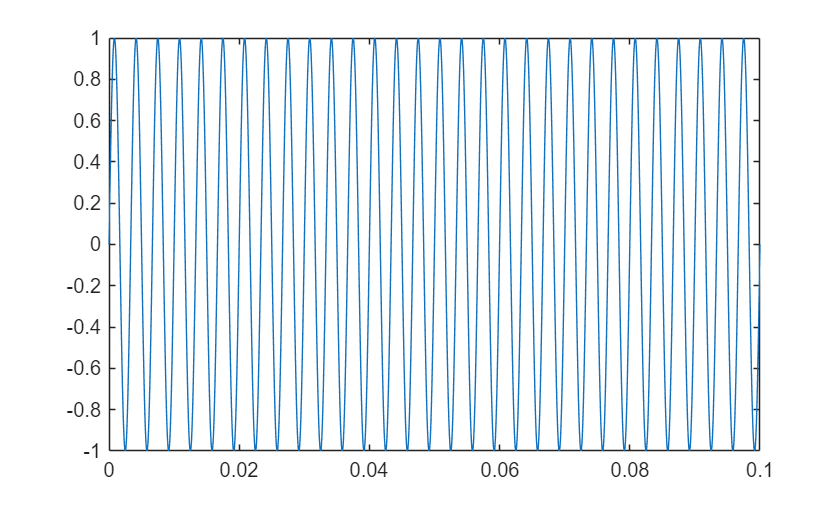

n1 = 300;
n2 = 600;

s1 = sin(2*pi*n1*t);
s2 = sin(2*pi*n2*t);

plot(t, s1);
xlim([0, 0.1]);

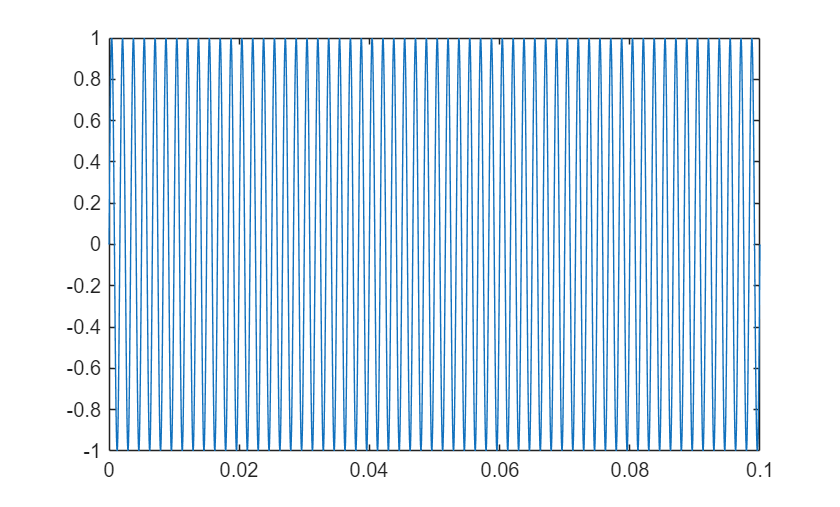

plot(t, s2);
xlim([0, 0.1]);

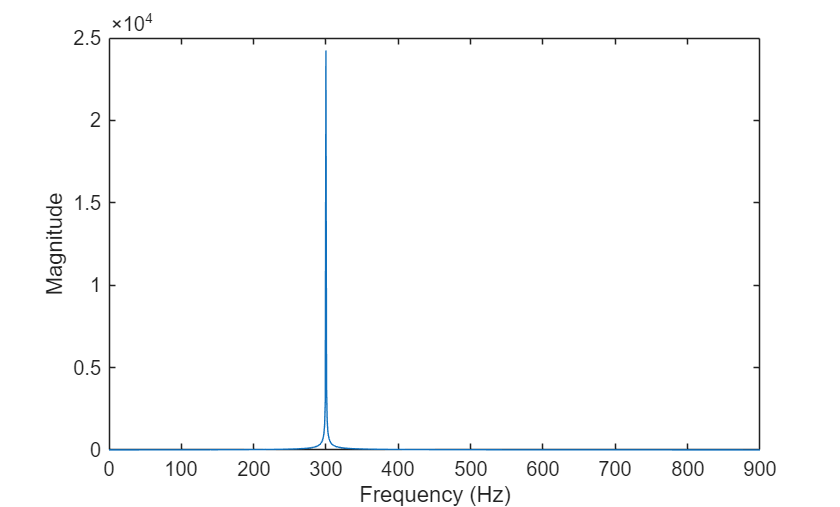

L = length(s1);
frequency_spectrum = fft(s1);
magnitude_spectrum = abs(frequency_spectrum);
shifted_spectrum = fftshift(magnitude_spectrum);
frequency = sampling_frequency/L*(-L/2:L/2-1);

plot(frequency, shifted_spectrum)
xlim([0, 900])
xlabel('Frequency (Hz)');
ylabel('Magnitude');

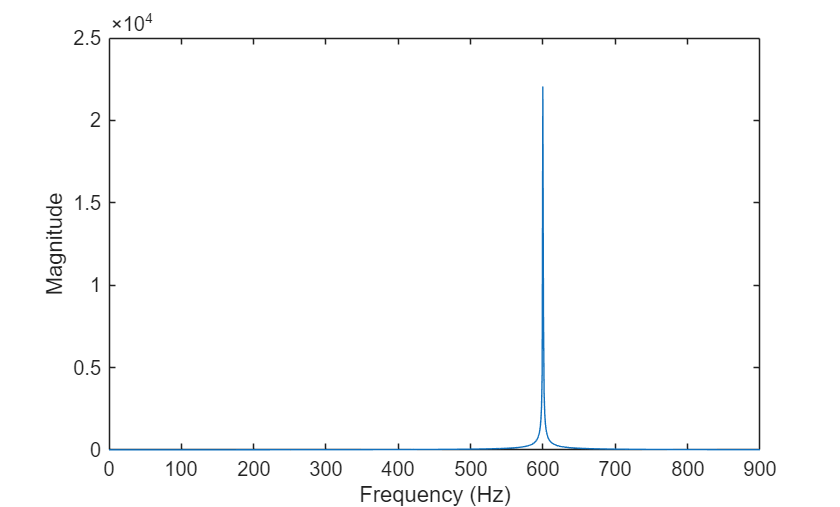

L = length(s2);
frequency_spectrum = fft(s2);
magnitude_spectrum = abs(frequency_spectrum);
shifted_spectrum = fftshift(magnitude_spectrum);
frequency = sampling_frequency/L*(-L/2:L/2-1);

plot(frequency, shifted_spectrum)
xlim([0, 900])
xlabel('Frequency (Hz)');
ylabel('Magnitude');

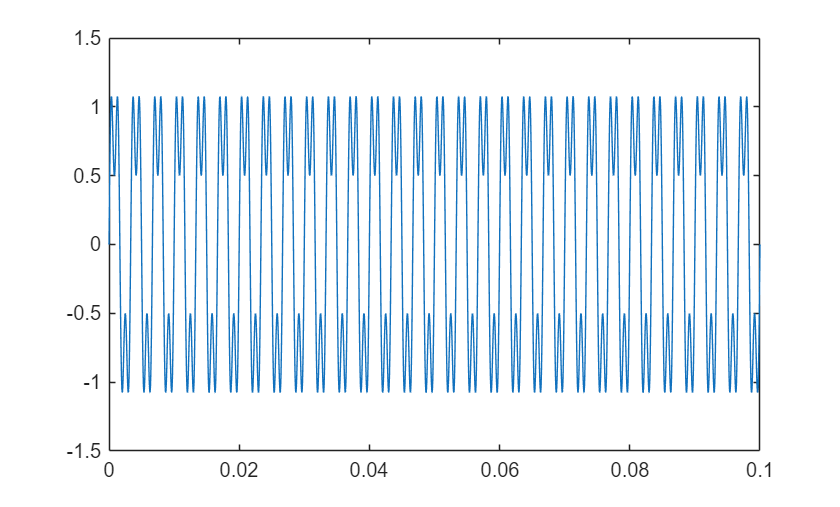

s3 = s1 + 0.5*sin(2*pi*900*t);
L = length(s3);
frequency_spectrum = fft(s3);
magnitude_spectrum = abs(frequency_spectrum);
shifted_spectrum = fftshift(magnitude_spectrum);
frequency = sampling_frequency/L*(-L/2:L/2-1);

plot(t, s3);
xlim([0, 0.1]);

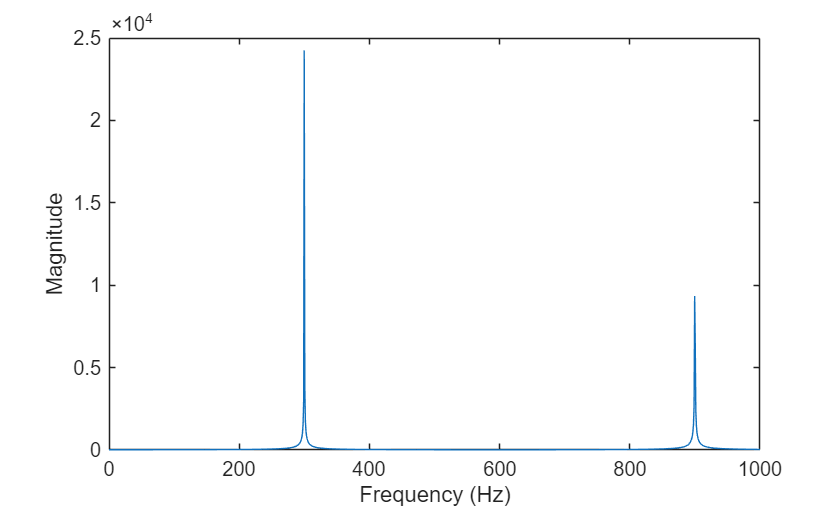

plot(frequency, shifted_spectrum)
xlim([0, 1000])
xlabel('Frequency (Hz)');
ylabel('Magnitude');